# Rate Model

load('Data\MeanData\MeanBinnedData.mat','S','M','t','varNames')

Mean data - dAdt compare to N and dNdt

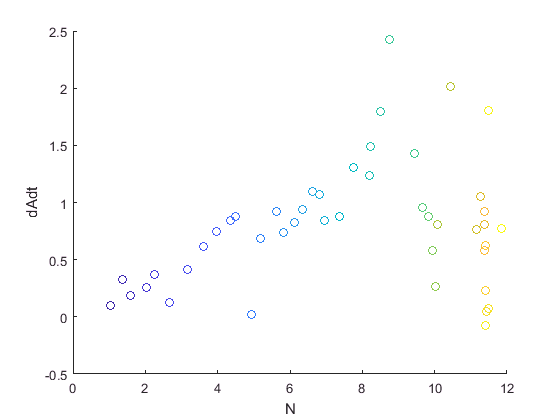

t0 = find(t==0); tend = find(t==135);
t1 = t(t0:tend);
A = M(12).Mean(t0:tend);
dAdt = diff(A)./3;
N = M(13).Mean(t0:tend);
dNdt = diff(N);

figure
scatter(N(1:end-1),dAdt,[],t1(1:end-1))
xlabel('N')
ylabel('dAdt')

r = corrcoef(N(1:end-1),dAdt);
r = r(1,2)

r = 0.2777

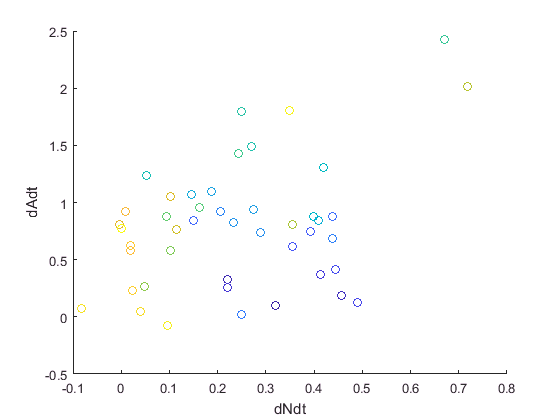


figure
scatter(dNdt,dAdt,[],t1(1:end-1))
xlabel('dNdt')
ylabel('dAdt')

r = corrcoef(dNdt,dAdt);
r = r(1,2)

r = 0.3735

Low correlations to both,

compared to N, increases and then decreases, reaches a peak, chek it for upto only day 81, when pop growth rate stops

figure
t81 = find(t1==81);
t2 = t1(t0:t81);
dAdt2 = dAdt(1:t81);
N81 = N(1:t81);

lm = fitlm(N81,dAdt2)

lm = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    ________    ________    _________
    (Intercept)    -0.10523     0.14236    -0.73914      0.46644
    x1              0.17294    0.023653      7.3116    9.159e-08

Number of observations: 28, Error degrees of freedom: 26
Root Mean Squared Error: 0.317
R-squared: 0.673,  Adjusted R-Squared 0.66
F-statistic vs. constant model: 53.5, p-value = 9.16e-08

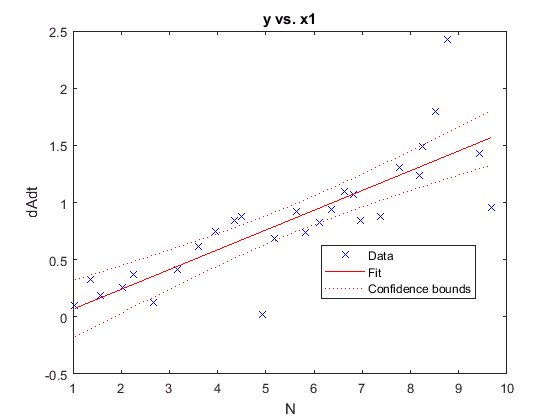

plot(lm)
xlabel('N')
ylabel('dAdt')

**Get OK fit, (rsq = 0.67),=> linear relationship, can say that each ant digs 0.17 cm^2 per day.**

## Find basic statistics for digging rate across experiments

UseNests = [2:8 10:13 15:18 20:29];
MeanDigRate = nan(29,1);
MedianDigRate = nan(29,1);
MaxDigRate = nan(29,1);
Nmax = nan(29,1);
MaxDigRate2 = nan(29,1);
Nmax2 = nan(29,1);
PercentLessThanOne = nan(29,1);

load('Data\LowerCamEndDate.mat','LowerCamEndDate')

for k=UseNests
    tag=['F',num2str(k)];
    load(['Data\',tag,'_Data.mat'],'A')
    % use only 1 data entry per day - only for lowercam
    if ~isempty(LowerCamEndDate{k})
        Ad = A(A.datenum<LowerCamEndDate{k},:);
        [~,idx_d,~] = unique(Ad.Date,'stable');
        Ad = A(idx_d,:);
        Ad = [Ad;A(A.datenum>=LowerCamEndDate{k},:)];
    else
        Ad = A;
    end
    % calc digging rate
    dAdt = table(A.runtime(1:end-1), diff(A.runtime),diff(A.TotalArea)./diff(A.runtime),A.Pop(1:end-1));
    dAdt.Properties.VariableNames = {'runtime','interval','DigRate','Pop'};
    % find wetting events or other instances of 2 photos at same hour and
    % filter them out
    DoublePhoto = find(dAdt.interval<(1/24));
    dAdt(DoublePhoto,:)=[];
    
%     % plot
%     figure
%     plot(dAdt.runtime,dAdt.DigRate,'-s')
%     title(tag)
    
    % identify digging events by intervals of higher digging rate than 1
    % cm^2/day
    %dAdt.DigRate(dAdt.DigRate<0) = 0;
    
    dAdt.nest = repmat(k,height(dAdt),1);
    
    % High digging rates
    [HighDigRates,runtimes,w,p] = findpeaks(dAdt.DigRate,dAdt.runtime,'MinPeakHeight',0.5,'MinPeakProminence',1,...
        'WidthReference','halfheight');
    idx = zeros(numel(runtimes),1);
    for i=1:numel(idx)
        idx(i) = find(dAdt.runtime == runtimes(i));
    end
    High_dAdt = dAdt(idx,:);
    High_dAdt.width = w;
    High_dAdt.prominence = p;
    
    % find stats
    MeanDigRate(k) = mean(dAdt.DigRate,'omitnan');
    MedianDigRate(k) = median(dAdt.DigRate,'omitnan');
    [MaxDigRate(k),I] = max(dAdt.DigRate);
    Nmax(k) = dAdt.Pop(I);
    [MaxDigRate2(k),I] = max(dAdt.DigRate(dAdt.Pop>1));
    pop2 = dAdt.Pop(dAdt.Pop>1);
    Nmax2(k) = pop2(I);
    PercentLessThanOne(k) = sum(dAdt.DigRate<1)./height(dAdt);
    PercentLessThanHalf(k) = sum(dAdt.DigRate<=0.5)./height(dAdt);
    
    if k==2
        DigRateAll = dAdt;
        HighAll = High_dAdt;
    else
        DigRateAll = [DigRateAll;dAdt];
        HighAll = [HighAll;High_dAdt];
    end
    disp(tag)

end

F2


F3


F4


F5


F6


F7


F8


F10


F11


F12


F13


F15


F16


F17


F18


F20


F21


F22


F23


F24


F25


F26


F27


F28


F29


summary(HighAll)

Variables:
    runtime: 229×1 double
        Values:
            Min       0.10507  
            Median     69.666  
            Max        209.72  
    interval: 229×1 double
        Values:
            Min       0.083322  
            Median       1.932  
            Max         12.321  
    DigRate: 229×1 double
        Values:
            Min       0.51376  
            Median     3.1959  
            Max        30.145  
    Pop: 229×1 double
        Values:
            Min            1   
            Median         7   
            Max            24  
            NumMissing     16  
    nest: 229×1 double
        Values:
            Min        2    
            Median    12    
            Max       29    
    width: 229×1 double
        Values:
            Min       0.03033
            Median       3.24
            Max        18.232
    prominence: 229×1 double
 

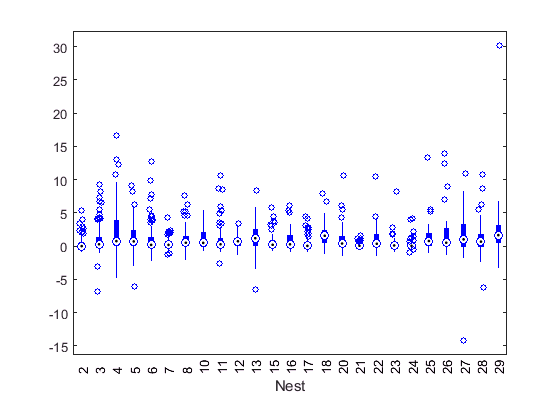

figure
boxplot(DigRateAll.DigRate,DigRateAll.nest,'PlotStyle','compact')
xlabel('Nest')

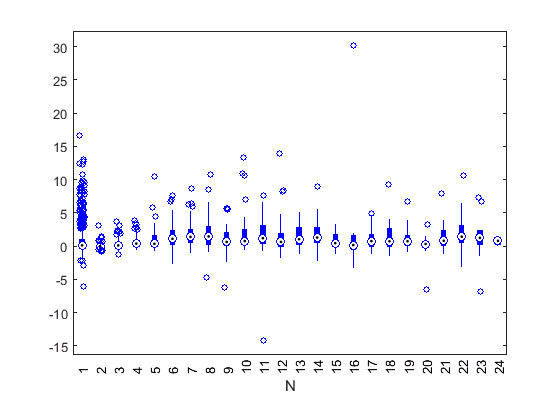



figure
boxplot(DigRateAll.DigRate,DigRateAll.Pop,'PlotStyle','compact')
xlabel('N')

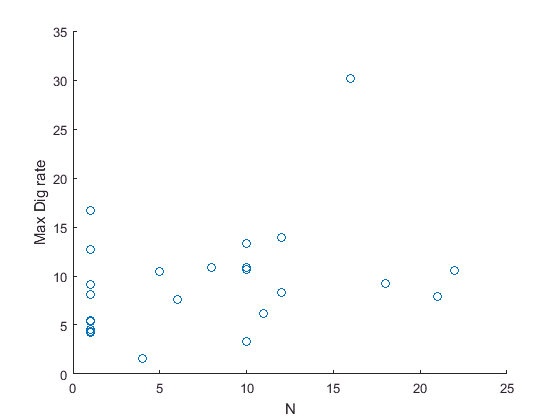




figure
scatter(Nmax,MaxDigRate)
xlabel('N')
ylabel('Max Dig rate')

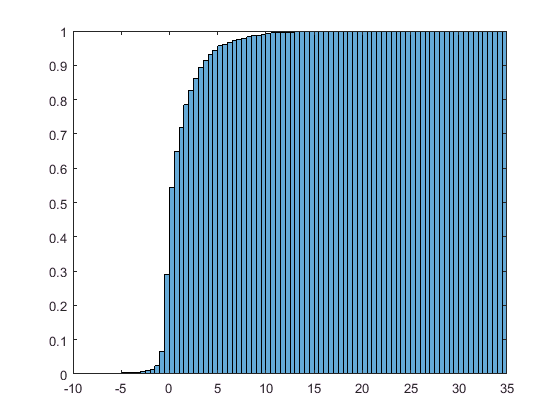


figure
histogram(DigRateAll.DigRate,-10:0.5:35,'Normalization','cdf')

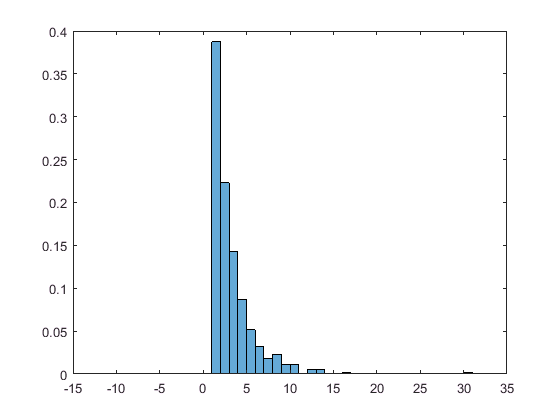


figure
histogram(DigRateAll.DigRate(DigRateAll.DigRate>=1),-15:1:35,'Normalization','probability')


% percent less than 1 cm per day
disp('mean - percent less than 1 cm^2 per day')

mean - percent less than 1 cm^2 per day


mean(PercentLessThanOne,'omitnan')

ans = 0.6558

disp('SD')

SD


std(PercentLessThanOne,'omitnan')

ans = 0.1406

disp('SEM')

SEM


std(PercentLessThanOne,'omitnan')./sqrt(length(UseNests))

ans = 0.0281


% pervent less than half cm^2 per daY
disp('MEAN - LESS THAN  HALF CM^2 PER DAY')

MEAN - LESS THAN  HALF CM^2 PER DAY


mean(PercentLessThanHalf,'omitnan')

ans = 0.4760

disp('SD')

SD


std(PercentLessThanHalf,'omitnan')

ans = 0.2372

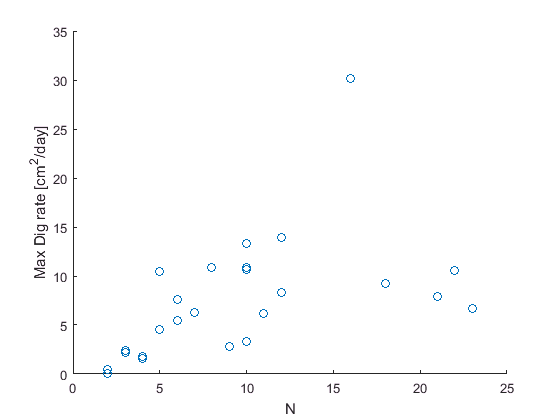


% max dig rates workers
figure
scatter(Nmax2,MaxDigRate2)
xlabel('N')
ylabel('Max Dig rate [cm^2/day]')

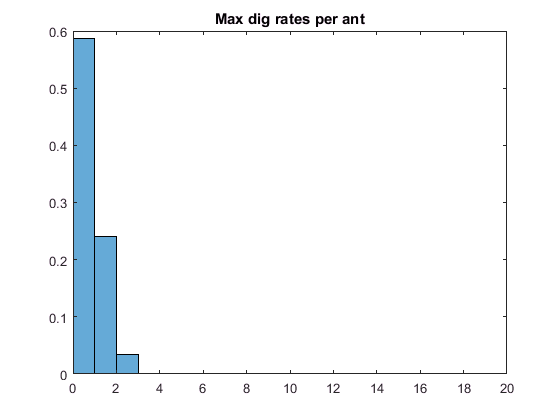



figure
histogram(MaxDigRate2./Nmax2,0:1:20,'Normalization','probability')
title('Max dig rates per ant')

mean(MaxDigRate2./Nmax2,'omitnan')

ans = 0.8050

std(MaxDigRate2./Nmax2,'omitnan')

ans = 0.5153

max(MaxDigRate2./Nmax2)

ans = 2.0987

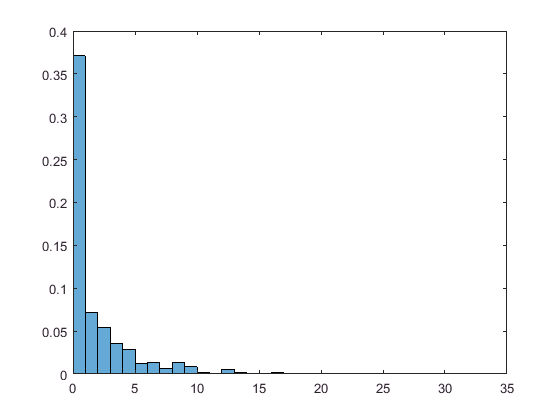


% single queen
figure
histogram(DigRateAll.DigRate(DigRateAll.Pop==1),0:1:35,'Normalization','probability')

## High Digging rates analysis

figure
disp('Dig rate')

Dig rate


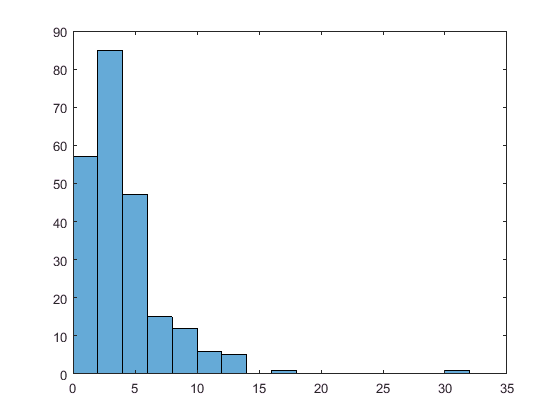

histogram(HighAll.DigRate)

mean(HighAll.DigRate)

ans = 4.1389

std(HighAll.DigRate)

ans = 3.3252


disp('duration of events')

duration of events


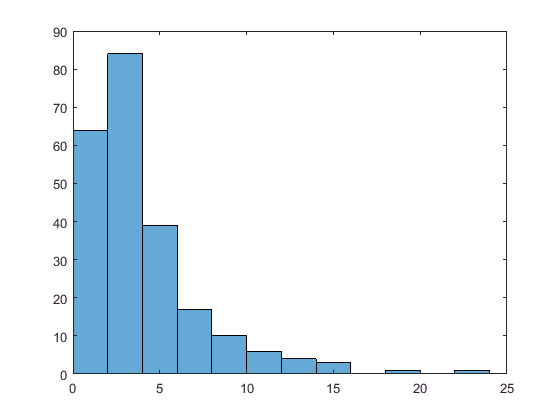

histogram(HighAll.width)

mean(HighAll.width)

ans = 3.9222

std(HighAll.width)

ans = 3.4289